## Instantiation: 

Creating a 2D zonotope using the zono class.

G = [1 0 1;0 1 1];  % Generator matrix with 3 generators
c = zeros(2,1);     % Center at the origin
Z = zono(G,c)

Z1 =   zono with properties:

     G: [2×3 double]
     c: [2×1 double]
     n: 2
    nG: 3


Creating a 2D constrained zonotope using the conZono class by three different methods.

A = ones(1,3);      % Constraint matrix with 1 constraint
b = 1;              % Constraint vector
C1 = conZono(G,c,A,b) % Constrained zonotope with 1 constraint

C1 =   conZono with properties:

     G: [2×3 double]
     c: [2×1 double]
     A: [1 1 1]
     b: 1
     n: 2
    nG: 3
    nC: 1


C2 = conZono(G,c)   % Constrained zonotope with 0 constraints (a zonotope)

C2 =   conZono with properties:

     G: [2×3 double]
     c: [2×1 double]
     A: [0×3 double]
     b: []
     n: 2
    nG: 3
    nC: 0


C3 = conZono(Z1)    % Recasting the zonotope Z as a conZono

C3 =   conZono with properties:

     G: [2×3 double]
     c: [2×1 double]
     A: [0×3 double]
     b: []
     n: 2
    nG: 3
    nC: 0


Creating a 2D hybrid zonotope using the hybZono class by 3 different methods.

H1 = hybZono(G,G,c,A,A,b) % Hybrid zonotope with 3 continuous and 3 binary generators and 1 constraint

H1 =   hybZono with properties:

     Gc: [2×3 double]
     Gb: [2×3 double]
      c: [2×1 double]
     Ac: [1 1 1]
     Ab: [1 1 1]
      b: 1
      n: 2
    nGc: 3
    nGb: 3
     nC: 1


H2 = hybZono(Z1)          % Recasting the zonotope Z as a hybZono

H2 =   hybZono with properties:

     Gc: [2×3 double]
     Gb: [2×0 double]
      c: [2×1 double]
     Ac: [0×3 double]
     Ab: []
      b: []
      n: 2
    nGc: 3
    nGb: 0
     nC: 0


H3 = hybZono(C1)          % Recasting the constrained zonotope C1 as a hybZono

H3 =   hybZono with properties:

     Gc: [2×3 double]
     Gb: [2×0 double]
      c: [2×1 double]
     Ac: [1 1 1]
     Ab: [1×0 double]
      b: 1
      n: 2
    nGc: 3
    nGb: 0
     nC: 1


## Arithmetic:

The Minkoski sum of sets using the overloaded + operator. Both sets can be either a zonotope, constrained zonotope, or hybrid zonotope (do not need to match).  The center of a set can also be shifted by adding a vector.

Z2 = Z1 + ones(2,1)  % Shifting the center of a zonotope

Z2 =   zono with properties:

     G: [2×3 double]
     c: [2×1 double]
     n: 2
    nG: 3


C4 = Z1 + C1         % Summing a zonotope and constrained zonotope

C4 =   conZono with properties:

     G: [2×6 double]
     c: [2×1 double]
     A: [0 0 0 1 1 1]
     b: 1
     n: 2
    nG: 6
    nC: 1


H4 = H1 + Z1         % Summing a hybrid zonotope and a zonotope

H4 =   hybZono with properties:

     Gc: [2×6 double]
     Gb: [2×3 double]
      c: [2×1 double]
     Ac: [1 1 1 0 0 0]
     Ab: [1 1 1]
      b: 1
      n: 2
    nGc: 6
    nGb: 3
     nC: 1


The affine mapping by matrix M or scaling by scalar m of a zonotope, constrained zonotope, or hybrid zonotope.

m = 5;
Z3 = m*Z2           % Scaling a zonotope to be 5 times larger (and shifting center)

Z3 =   zono with properties:

     G: [2×3 double]
     c: [2×1 double]
     n: 2
    nG: 3


M = [1 1;0 1];
H5 = M*H4           % Affine tranformation of a hybrid zonotope by a matrix

H5 =   hybZono with properties:

     Gc: [2×6 double]
     Gb: [2×3 double]
      c: [2×1 double]
     Ac: [1 1 1 0 0 0]
     Ab: [1 1 1]
      b: 1
      n: 2
    nGc: 6
    nGb: 3
     nC: 1


## Plotting

Plot a zonotope in 2D

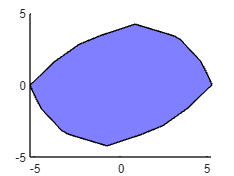

rng(1)
nG = 10;
Z4 = zono(2*rand(2,nG)-1,zeros(2,1));
figure;
tic;
plot(Z4,'b',0.5)

toc

Elapsed time is 0.609354 seconds.


Plot a zonotope in 3D

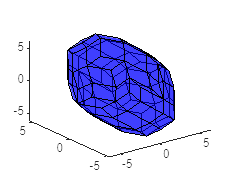

nG = 10;
Z4 = zono(2*rand(3,nG)-1,zeros(3,1));
figure;
tic;
plot(Z4,'b',0.5)

toc

Elapsed time is 0.123218 seconds.


## Optimization

Check to see if a point is contained in a constrained zonotope 

C3.checkPointContain([0;0],true); % Is contained

    RESULT: Point is contained.


C3.checkPointContain([10;10],true); % Is not contained

    RESULT: Point is not contained.


Check to see if a zonotope is contained within another zonotope 

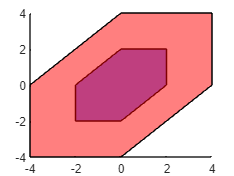

Z1_double = Z1;
Z1_double.G = 2*Z1_double.G;
figure();
Z1.plot('b',0.5);
Z1_double.plot('r',0.5);

Z1.checkSetContain(Z1_double,true); % Is not contained

    RESULT: Set is not contained.


Z1_double.checkSetContain(Z1,true); % Is contained

    RESULT: Set is contained.


Check to see if a zonotope is contained within another zonotope, from: Sadraddini, Sadra and Tedrake, Russ. 2019. "Linear Encodings for Polytope Containment Problems." 2019 IEEE 58th Conference on Decision and Control (CDC)

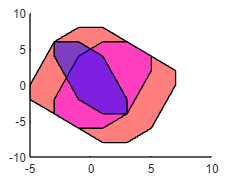

Z5 = zono([1,0,0,1,1;0,-1,0,-1,-3],[0;1]);
Z6 = zono([1,0,1,1,1,2;0,1,1,-1,3,-2],[1;0]);
Z7 = Z6;
Z7.G = Z7.G(:,1:end-1); % dropping the last column 
figure();
Z6.plot('r',0.5);
Z7.plot('m',0.5);
Z5.plot('b',0.5);

Z6.checkSetContain(Z5,true); % Is contained

    RESULT: Set is contained.


Z7.checkSetContain(Z5,true); % Is not contained

    RESULT: Set is not contained.


Check to see if a constrained zonotope is contained within another constrained zonotope:

Z8 = conZono([-1,3,4,0,0;4,-2,-5,0,0],[0;0],[-1,3,4,6.5,0;4,-2,-5,0,8],[-1.5;-3]);
Z9 = conZono([0,3.17,2.38,-0.79;0,-3.97,-1.59,3.17],[-1.34;1.03],[1,-0.63,-0.25,0.5],[-0.38]);
figure();
Z9.plot('r',0.5);

MOSEK Version 9.1.9 (Build date: 2019-11-21 11:34:40)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86



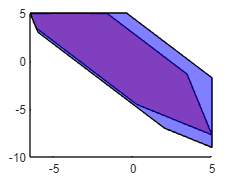

Z8.plot('b',0.5);

Z9.checkSetContain(Z8,true); % Is contained

    RESULT: Set is contained.


Check to see if a constrained zonotope is empty

C1.checkEmpty(true); % Is not empty

    RESULT: Set is not empty.


C1_empty = C1;
C1_empty.A = [C1_empty.A; ones(1,C1_empty.nG)];
C1_empty.b = [C1_empty.b; 2];
C1_empty.checkEmpty(true); % Is empty

    RESULT: Set is empty.
